# Step Size Expectation

Script to compute the statistical expectation of the step size 

dimen = 4096; 
pop_size = 40;
weights = rankweight(pop_size,pop_size/2);
mu = 0.5;
basis_norm = 100;

grad_vect = randn(1, dimen);
score_lin = @(x) x * grad_vect';

## Compute the expected gradient norm

%% Pure noise score
score_fun = @(x) randn(size(x,1),1);
basis_vec = zeros(1, dimen);
basis_vec(1) = basis_norm; 
ExpectStepSize = sqrt(dimen * sum(weights.^2)) * mu;
disp(ExpectStepSize)

    9.5154



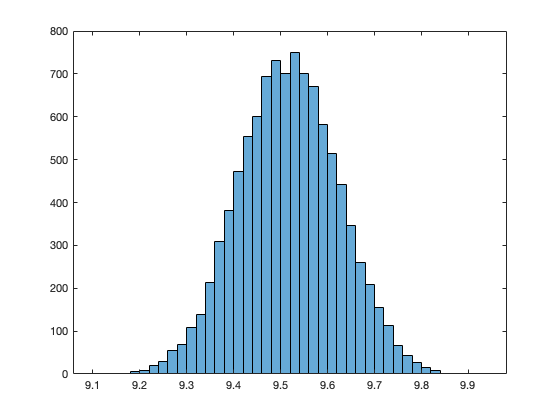

gradnorm_ctr=zeros(1,10000);
for i = 1:10000
tang_codes = mu * randn(pop_size, dimen);
f_basis = score_fun(basis_vec);
f_exp = score_fun(basis_vec + tang_codes);
[sorted_f, sort_arg] = sort(f_exp);
hagrad = weights * tang_codes(sort_arg, :);
gradnorm_ctr(i) = norm(hagrad);
end
figure, clf, histogram(gradnorm_ctr)

fprintf("Pure Noise Score\tMean norm of grad %.3f, std %.3f", mean(gradnorm_ctr), std(gradnorm_ctr))

Mean norm of grad 9.517, std 0.105

mean(gradnorm_ctr)

ans = 9.5174

std(gradnorm_ctr)

ans = 0.1054

fprintf("Pure Noise Score\tMean norm of grad %.3f, std %.3f", mean(gradnorm_ctr), std(gradnorm_ctr))

Pure Noise Score	Mean norm of grad 9.517, std 0.105

score_fun = score_lin;
basis_vec = zeros(1, dimen);
basis_vec(1) = basis_norm; 
ExpectStepSize = sqrt(dimen * sum(weights.^2)) * mu;
disp(ExpectStepSize)

    9.5154



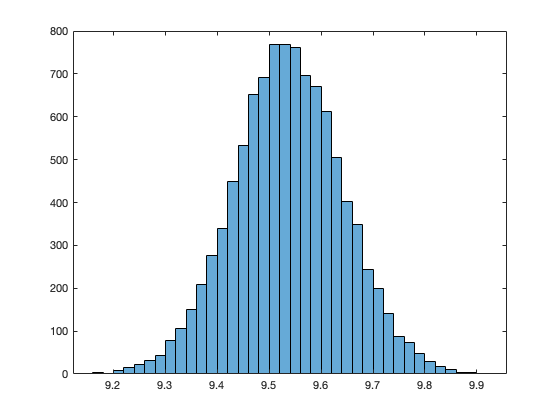

gradnorm=zeros(1,10000);
for i = 1:10000
tang_codes = mu * randn(pop_size, dimen);
f_basis = score_fun(basis_vec);
f_exp = score_fun(basis_vec + tang_codes);
[sorted_f, sort_arg] = sort(f_exp);
hagrad = weights * tang_codes(sort_arg, :);
gradnorm(i) = norm(hagrad);
end
figure, clf, histogram(gradnorm)

fprintf("Linear Model Score\tMean norm of grad %.3f, std %.3f", mean(gradnorm), std(gradnorm))

Linear Model Score	Mean norm of grad 9.537, std 0.105

mean(gradnorm)

ans = 9.5370

std(gradnorm)

ans = 0.1047

In 4096 Dimension, either using a linear model or a random noise model as score the rank based weighted sum of the samples will be same of similar norm. (estimated from 10000 run simulation. )

`Pure Noise Score	Mean norm of grad 9.517, std 0.105`

`Linear Model Score	Mean norm of grad 9.537, std 0.105`

## Norm of Exploration Vector 

Compute the norm of exploration vector given a basis vector of certain norm and a $\mu$ of exploration. 


$$u=v+\mu T\\
T\sim \mathcal N(0,I)$$


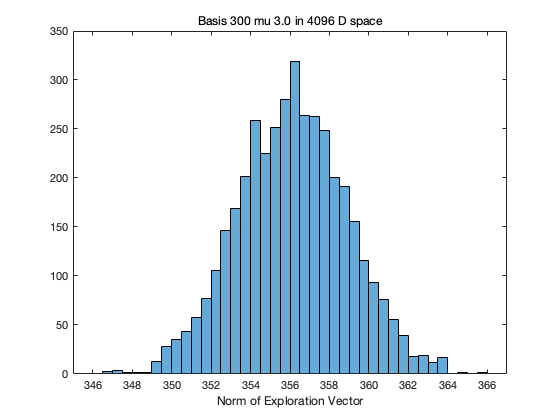

basis_norm = 300;
mu = 3;
dimen = 4096; 

basis_vec = zeros(1, dimen);
basis_vec(1) = basis_norm; 
tang_codes = mu * randn(4000, dimen);
new_codes = basis_vec+tang_codes;
newnorms = sqrt(sum(new_codes.^2,2));
figure, clf, histogram(newnorms), xlabel("Norm of Exploration Vector")
title(sprintf("Basis %.f mu %.1f in %d D space", basis_norm, mu, dimen))

sqrt(dimen) * mu

ans = 32

## Expected Angle distribution between 2 Vectors

Generally the higher the dimension, the more possible that 2 vectors are kind of orthogonal to each other, more precisely, the $\cos$ angle between 2 vectors will distribute center at 0, the std of which scale as $1/\sqrt D$, inverse to the scaling of norm expectation of a multi-variate unit Gaussian. For reference, 

In 10D space

`Angle in deg Mean 89.88, std 19.079`

`Cos Angle Mean 0.0020, std 0.3163`

In 50D space 

`Angle in deg Mean 90.07, std 8.147`

`Cos Angle Mean -0.0011, std 0.1408`

in 4096D space 

`Angle in deg Mean 90.00, std 0.883`

`Cos Angle Mean -0.0000, std 0.0154`

vec1 = zeros(1, dimen);
vec1(1) = 1; 
vec2 = randn(1, dimen);
vec2 = vec2 / norm(vec2); 
dot(vec1,vec2)

ans = 0.0014

dimen = 10%4096; % 50

dimen = 10

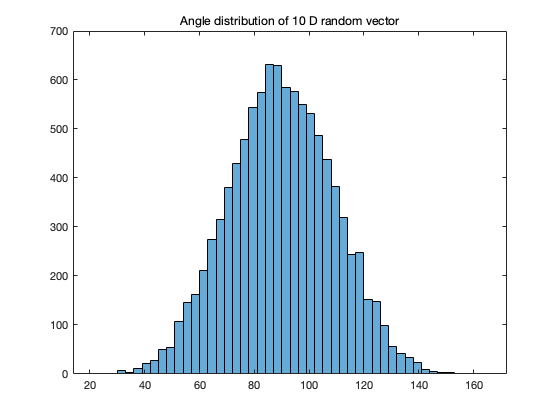

vec1 = zeros(1, dimen);
vec1(1) = 1; 
vec2 = randn(10000, dimen);
vec2 = vec2 ./ norm_axis(vec2,2); 
cosang = vec2 * vec1';
angs = acos(cosang);
angs_deg = angs / pi * 180;
figure, histogram(angs_deg), title(sprintf("Angle distribution of %d D random vector", dimen))

std(angs_deg) % spread of angle in degree ~ 0.9 deg

ans = 19.0792

std(cosang) % spread of cosine angle between 2 vectors. % 0.015

ans = 0.3163

fprintf("Angle in deg Mean %.2f, std %.3f\n" + ...
    "Cos Angle Mean %.4f, std %.4f", mean(angs_deg), std(angs_deg),...
    mean(cosang), std(cosang))

Angle in deg Mean 89.88, std 19.079
Cos Angle Mean 0.0020, std 0.3163

dimen = 4096%4096; % 50

dimen = 4096

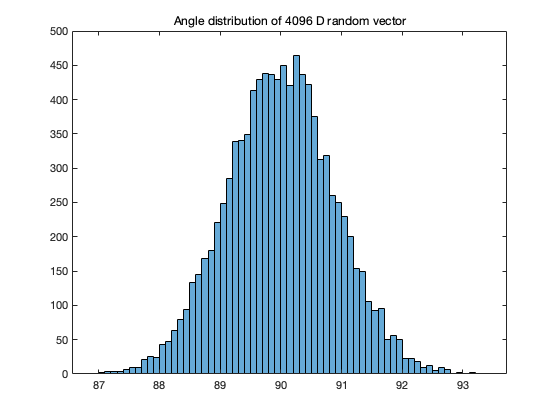

vec1 = zeros(1, dimen);
vec1(1) = 1; 
vec2 = randn(10000, dimen);
vec2 = vec2 ./ norm_axis(vec2,2); 
cosang = vec2 * vec1';
angs = acos(cosang);
angs_deg = angs / pi * 180;
figure, histogram(angs_deg), title(sprintf("Angle distribution of %d D random vector", dimen))

std(angs_deg) % spread of angle in degree ~ 0.9 deg

ans = 0.8832

std(cosang) % spread of cosine angle between 2 vectors. % 0.015

ans = 0.0154

fprintf("Angle in deg Mean %.2f, std %.3f\n" + ...
    "Cos Angle Mean %.4f, std %.4f", mean(angs_deg), std(angs_deg),...
    mean(cosang), std(cosang))

Angle in deg Mean 90.00, std 0.883
Cos Angle Mean -0.0000, std 0.0154

### 
$$\|v+u\|=\sqrt{\|u\|^2+\|v\|^2+2\|u\|\|v\|cos(u,v)}$$


function norms = norm_axis(arr, axis)
norms = sqrt(sum(arr.^2, axis));
end